# ΨΗΦΙΑΚΕΣ ΤΗΛΕΠΙΚΟΙΝΩΝΙΕΣ

## 1ο σετ Εργαστηριακών Ασκήσεων 

Λουδάρος Ιωάννης - ΑΜ 1067400

% Μεταφορά του Current Folder στον κατάλογο του αρχείου ώστε να υπάρχει
% πρόσβαση στις απαιτούμενες συναρτήσεις.

cd(fileparts(matlab.desktop.editor.getActiveFilename))

### Μέρος 1

#### LloydMax 

[Άνοιγμα Ορισμού](matlab:open('./LloydMax.m'))

Κατασκευάστηκε η παρακάτω συνάρτηση 

Είσοδοι:

- $x$ : Το σήμα εισόδου υπό την μορφή διανύσματος

- $N
$: Ο αριθμός των bits/sample που θα χρησιμοποιηθούν

- $max_{value$ : Η μέγιστη αποδεκτή τιμή του σήματος εισόδου

- $min_{value}$ : Η ελάχιστη αποδεκτή τιμή του σήματος εισόδου

Έξοδοι:

- $x_q$ : Το κωδικοποιημένο διάνυσμα εξόδου μετά από $K_{max}$ επαναλήψεις του αλγορίθμου

- $\text{centers}$ : Τα κέντρα των περιοχών κβάντισης μετά από $K_{max}$ επαναλήψεις του αλγορίθμου.

- $D$ : Διάνυσμα που περιέχει τις τιμές [$D_1 : D_{K_{max}}$], όπου το $D_i$ αντιστοιχεί στη μέση παραμόρφωση την i-οστή επανάληψη του αλγορίθμου

Η συνάρτηση ορίζεται στο αρχείο LloydMax.m που βρίσκεται στον ίδιο κατάλογο με το παρόν αρχείο.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
x = 120*rand(1, 100)-10

x =    36.5841   98.8007  104.5081   95.9543   19.5072   92.6621   86.6704   -9.0487  105.7492  109.6297   -5.2088   77.7368   14.2602    1.8210   30.4976   63.9436   77.2636   94.3305   54.9822   66.0171  104.8748   20.9845   76.4941  105.0688   -8.0663  100.2992  107.1354   96.7704   63.6058   95.1676  102.3061   45.7920   85.8649   11.1510    1.2587   24.8832    2.8590   73.7255   89.2824   76.2755   97.4788  109.0620   95.4966   60.7006   94.2957   67.5660   54.5798   -6.8608   45.0214   86.1624






[xq, centers, D] = LloydMax(x, N, min_value, max_value)

xq = 100×4 char array
    '0101'
    '1111'
    '1111'
    '1111'
    '0010'
    '1111'
    '1110'
    '0000'
    '1111'
    '1111'
    '0000'
    '1100'
    '0001'
    '0000'
    '0100'
    '1010'
    '1100'
    '1111'
    '1000'
    '1010'
    '1111'
    '0010'
    '1100'
    '1111'
    '0000'
    '1111'
    '1111'
    '1111'
    '1010'
    '1111'
    '1111'
    '0111'
    '1110'
    '0001'
    '0000'
    '0011'
    '0000'
    '1011'
    '1110'
    '1100'
    '1111'
    '1111'
    '1111'
    '1001'
    '1111'
    '1010'
    '1000'
    '0000'
    '0111'
    '1110'
    '1010'
    '0100'
    '0101'
    '0101'
    '0001'
    '0101'
    '1001'
    '0100'
    '1010'
    '0001'
    '1000'
    '0110'
    '0101'
    '0100'
    '0001'
    '0000'
    '0111'
    '1110'
    '0101'
    '0111'
    '0000'
    '0000'
    '0110'
    '0111'
    '0001'
    '0110'
    '0111'
    '1000'
    '0110'
    '0000'
    '0001'
    '0000'
    '0101'
    '0000'
    '0111'
    '1111'
    '0101'
    '0000'
    '1100'

centers =     1.3612   11.8550   19.8159   23.5623   31.3448   35.5931   41.1177   46.6772   54.5583   59.1052   65.7994   72.2539   77.3044   82.5294   87.2103   97.9916


D =    10.6034    2.7119    2.6609    2.6609


#### Adaptive Delta Modulation

([Άνοιγμα Ορισμών](matlab:open('./adm.m')))

Για την Προσαρμοστική Κωδικοποίηση Δέλτα δημιουργήθηκαν 2 συναρτήσεις.

**1. O Κωδικοποιητής **

Είσοδοι:

- x : Το αρχικό μας σήμα.

- M : Ο παράγοντας υπερδειγματοληψίας.

Έξοδοι:

- xq : Το κωδικοποιημένο σήμα.

**2. Ο Αποκωδικοποιητής**

Είσοδοι:

- xq : Το κωδικοποιημένο σήμα που παραλάβαμε.

- M: Ο παράγωντας υπερδειγματοληψίας.

Έξοδοι:

- decoded : Το αποκωδικοποιημένο σήμα.

**Παράδειγμα χρήσης:**

min_value = 1;
max_value = 100;
N = 4;
x = 120*rand(1, 100)-10

x =    60.3299   90.2041   49.3117   58.4354   64.1307   84.8743   93.9766   24.3517  108.1739   22.6902   -8.7545   15.0589   88.2856   25.4600    3.8031   57.9511   31.6263   58.0495   25.4692   38.7460   33.1113   31.0760   84.9999   -3.9648    0.6000   21.4574   98.1632   37.7326   32.5262   81.1656   47.7510   -8.6019   -6.7132   67.9226   89.3624   34.6949   -6.8726    6.8905   -3.1101   -4.5736    4.5554   59.7600   76.5484   86.3970   10.3917   79.7871   -9.0941   62.9653   50.4384   11.2577






[xq, centers, D] = LloydMax(x, N, min_value, max_value)

xq = 100×4 char array
    '1001'
    '1110'
    '0111'
    '1001'
    '1010'
    '1101'
    '1111'
    '0011'
    '1111'
    '0011'
    '0000'
    '0001'
    '1110'
    '0011'
    '0000'
    '1001'
    '0100'
    '1001'
    '0011'
    '0110'
    '0100'
    '0100'
    '1101'
    '0000'
    '0000'
    '0010'
    '1111'
    '0101'
    '0100'
    '1101'
    '0111'
    '0000'
    '0000'
    '1011'
    '1110'
    '0101'
    '0000'
    '0001'
    '0000'
    '0000'
    '0000'
    '1001'
    '1100'
    '1110'
    '0001'
    '1100'
    '0000'
    '1010'
    '0111'
    '0001'
    '1111'
    '0100'
    '1111'
    '1010'
    '1111'
    '0000'
    '1111'
    '1010'
    '1111'
    '1010'
    '1111'
    '0101'
    '1010'
    '0000'
    '0100'
    '0111'
    '0001'
    '1101'
    '0101'
    '0000'
    '0010'
    '1111'
    '0000'
    '1100'
    '1111'
    '1101'
    '0001'
    '1010'
    '1101'
    '0001'
    '0001'
    '1001'
    '1010'
    '0110'
    '0010'
    '0011'
    '0110'
    '1010'
    '0101'

centers =     1.6737   10.2385   20.0967   24.6764   31.7690   36.3854   39.3834   48.2298   53.7919   58.7363   65.0528   69.1201   78.3068   82.9838   88.9499   98.6126


D =     9.1548    2.8797    2.6852    2.6166    2.5858    2.5858


#### Πηγές που θα χρησιμοποιηθούν

**Α. AR(1) διαδικασία**

L=10000;
x=randn(L,1);
a1=0.9;
a2=0.01;

ar1 = filter(1,[1; -a1], x)

ar1 =    -0.3086
   -0.4728
   -1.3629
   -2.0633
   -2.0367
   -0.6807
    0.2526
    1.0039
    1.1404
    0.0705


ar2 = filter(1,[1; -a2], x)

ar2 =    -0.3086
   -0.1982
   -0.9394
   -0.8461
   -0.1882
    1.1504
    0.8768
    0.7853
    0.2448
   -0.9534


**Β. Εικόνα**

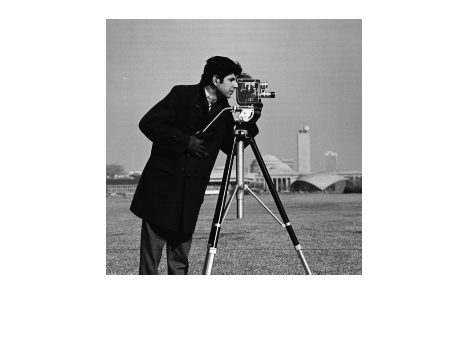

load cameraman.mat
imshow(uint8(i));

x=i(:);
x=((x-128)/128);

#### Ζητούμενο 1

![...]

#### Ζητούμενο 2

![...]

### Μέρος 2

Για το δεύτερο μέρος κατασκευάστηκαν πολλαπλές συναρτήσεις που βρίσκονται στον ίδιο κατάλογο με το παρόν αρχείο.

#### Ο Mapper

[Άνοιγμα Ορισμού](matlab:open('./mapper.m'))

**Είσοδοι**

- bin_seq : Δυαδική ακολουθία προς μετατροπή σε σύμβολα.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων θα είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

**Έξοδοι**

- symbol_seq : Η ακολουθία συμβόλων που προκύπτει.

- chopped : Τα τελευταία bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν ήταν αρκετά για να γίνουν map.  

#### Ο Demapper

[Άνοιγμα Ορισμού](matlab:open('./demapper.m'))

**Είσοδοι**

- symbol_seq : Η ακολουθία συμβόλων που παραλαμβάνεται.

- Μ : Το πλήθος των συμβόλων.

- gray : Επιλογή για το αν η ακολουθία συμβόλων είναι κωδικοποιημένη κατά gray (1) ή όχι (0).

- chopped : bits της άρχικης ακολουθίας που αποκόπηκαν γιατί δεν μπορούσαν να γίνουν map. Θα προστεθούν απλά στο τέλος, αν δοθούν.

**Έξοδοι**

- bin_seq : Δυαδική ακολουθία που προκύπτει από τα σύμβολα.

**Παράδειγμα χρήσης**

binary_seq = randsrc(100,1,[0, 1])
M=8;
gray=0;

[chopped, symbol_seq] = mapper (binary_seq, 8, gray)

binary_seq = demapper(symbol_seq, M, gray,chopped)

#### Ο Modulator

[Άνοιγμα Ορισμού](matlab:open('./modulator.m'))

**Είσοδοι**

- symbol_seq : Τα προς μετάδοση σύμβολα.

- Μ : Το πλήθος των συμβόλων.

**Έξοδοι**

- modulated : Ο προς μετάδoση παλμός.

#### Ο Demodulator

[Άνοιγμα Ορισμού](matlab:open('./demodulator.m'))

**Είσοδοι**

- received_signal : Το σήμα που παραλάβαμε από το κανάλι.

**Έξοδοι**

- demodulated : Το demodulated σήμα.

**Παράδειγμα χρήσης**

#### O Detector

[Άνοιγμα Ορισμού](matlab:open('./detector.m'))

**Είσοδοι**

- demodulated : Το αποδιαμορφωμένο σήμα από το κανάλι.

- Μ : Το πλήθος των συμβόλων.

**Έξοδοι**

- symbol_seq : Η ακολουθία συμβόλων που εξάγαμε.

#### Ζητούμενο 1

#### Ζητούμενο 2

#### Ζητούμενο 3

#### Ζητούμενο 4

#### Ζητούμενο 5

binary_seq =      0
     0
     0
     0
     0
     1
     1
     1
     0
     0


chopped = 0

symbol_seq =      0     1     6     1     0     5     3     6     6     3     1     3     3     2     4     0     2     7     4     5     4     5     3     7     0     1     7     3     1     1     6     6     6


binary_seq = "0000011100010001010111101100110010110110101000000101111001011001010111110000011110110010011101101100"